# Generating PDM Wavetable Samples

[*Matthias Wolff*](https://www.b-tu.de/en/fg-kommunikationstechnik/team/staff/prof-dr-ing-habil-matthias-wolff)

[BTU Cottbus-Senftenberg](https://www.b-tu.de/en/), [Chair of Communications Engineering](https://www.b-tu.de/en/fg-kommunikationstechnik)

## **1   PDM Characteristic Curve**

fprintf(['_____________________________________________________________________\n' ...
  '1 PDM Characteristic Curve']);

_____________________________________________________________________
1 PDM Characteristic Curve

### 1.1   Piecewise Linear Function

fprintf('1.1 Piecewise Linear Function\n');

1.1 Piecewise Linear Function


As explained in Section "Phase Distortion Modulation" in the report, the phase distortion characteristic curve consists of two straigt sections

    $f_1(\varphi)=a\varphi$,        $0\leq\varphi\leq\varphi_B$,    running through the points $(0,0)$ and $(\varphi_B,\pi)$ and

    $f_2(\varphi) = b\varphi+c$,  $\varphi_B\leq \varphi< 2\pi$,  running through the points $(\varphi_B,\pi)$ and $(2\pi,2\pi)$.

Here, $\varphi_B$ denotes the phase angle of the bend, i.e., the intersection of the two straight sections. I will refer to $(\varphi_b,\pi)$ as the "bend" point. Taking the slope $a$ of the first section as a variable parameter with $a\geq 1$, we can compute $\varphi_B$, $b$, and $c$.

syms a b c phi phiB real;
assume(a>=0);
eqns = [           ...
  a*phiB   == pi,  ...
  b*phiB+c == pi,  ...
  b*2*pi+c == 2*pi ...
];
S = solve(eqns,[phiB,b,c]);
phiB = simplify(S.phiB); fprintf('  phiB ='); disp(phiB);

  phiB =

$$\frac{\pi }{a}$$

b    = simplify(S.b);    fprintf('  b ='   ); disp(b);

  b =

$$\frac{a}{2\,a-1}$$

c    = simplify(S.c);    fprintf('  c ='   ); disp(c);

  c =

$$\frac{2\,\pi \,\left(a-1\right)}{2\,a-1}$$

Hence, the phase distortion modulation characteristics curve is

    
$$\varphi_{\text{PD}}(\varphi) = \begin{cases}
  a\varphi &\text{for } 0\leq\varphi<\frac{\pi}{a}\\
  \frac{a\varphi+2\pi(a-1)}{2a-1} &\text{for }\frac{\pi}{a}\leq\varphi<2\pi.
\end{cases}$$


This characteristic is implemented by the function `phipd=PDMcc(phi,a)` in the appendix below.

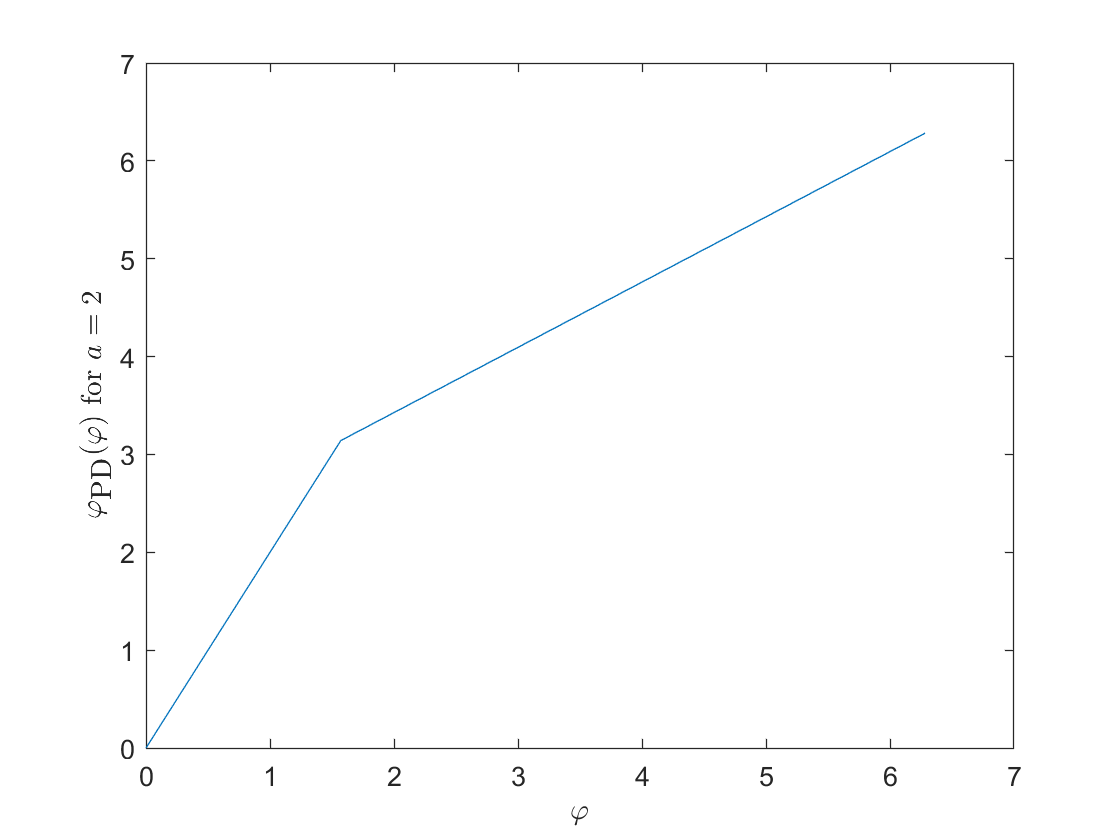

x = 0:0.01*pi:2*pi;
y = PDMcc(x,2);
plot(x,y);
xlabel('$$\varphi$$','Interpreter','latex');
ylabel('$$\varphi_{\mbox{PD}}(\varphi)$$ for $$a=2$$','Interpreter','latex');

### 1.2   Modulation Angle Parameter

fprintf('\n1.2 Modulation Angle Parameter');


1.2 Modulation Angle Parameter

The modulation angle parameter $\vartheta$ can be computed from the slope parameter $a$ as follows

    $\vartheta = 180°-\arctan(a)+\arctan(b) = 180°-\arctan(a)+\arctan\left(\frac{a}{2a-1}\right)$.

fprintf('Modulation angle theta as function of slope paramerter a');

Modulation angle theta as function of slope paramerter a

fprintf('- Symbolic solution');

- Symbolic solution

syms theta real;
assume(theta>0 & theta<=pi & a>=1);
eqns = theta==pi-atan(a)+atan(b);
solve(eqns,a);

There seems to be no explicit inverse function (and I do not know it any better). Hence we plot $\vartheta(a)$and compute a lookup table.

fprintf('- Plot');

- Plot

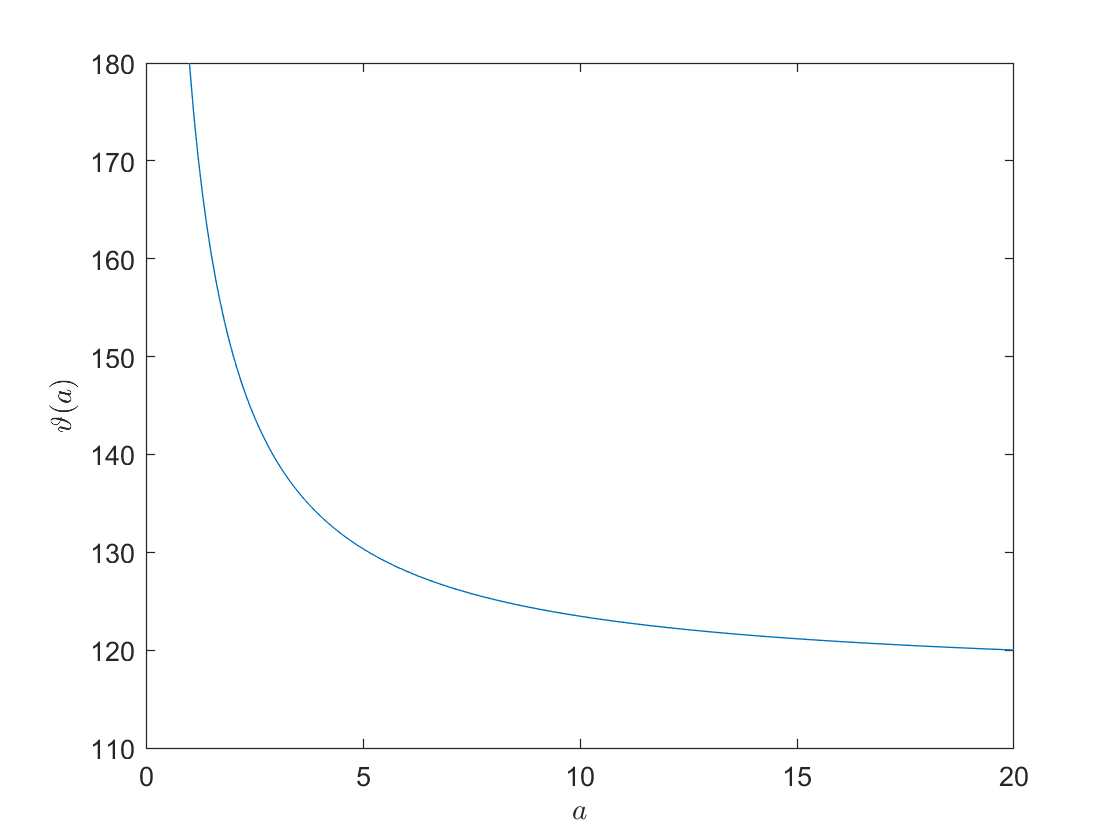

x = 1:0.1:20;
y = a2theta(x);
plot(x,y);
ylim([110 180]);
xlabel('$$a$$','Interpreter','latex');
ylabel('$$\vartheta(a)$$','Interpreter','latex');


fprintf('- Lookup table');

- Lookup table

for i=120:5:180
  theta = i/180*pi;
  S = solve(theta==pi-atan(a)+atan(b),a); 
  fprintf('  phi = %d°\n  -> a = %g =',i,eval(S)); disp(S);
end

  phi = 120°
  -> a = 20.0702 =

$$-\frac{\sqrt{3}+\sqrt{7}+1}{\sqrt{3}-2}$$

  phi = 125°
  -> a = 8.18719 =

$$-\frac{\tan\left(\frac{11\,\pi }{36}\right)+\sqrt{2\,{\tan\left(\frac{11\,\pi }{36}\right)}^{2}+1}+1}{\tan\left(\frac{11\,\pi }{36}\right)-2}$$

  phi = 130°
  -> a = 5.13641 =

$$-\frac{\tan\left(\frac{5\,\pi }{18}\right)+\sqrt{2\,{\tan\left(\frac{5\,\pi }{18}\right)}^{2}+1}+1}{\tan\left(\frac{5\,\pi }{18}\right)-2}$$

  phi = 135°
  -> a = 3.73205 =

$$\sqrt{3}+2$$

  phi = 140°
  -> a = 2.92095 =

$$-\frac{\tan\left(\frac{2\,\pi }{9}\right)+\sqrt{2\,{\tan\left(\frac{2\,\pi }{9}\right)}^{2}+1}+1}{\tan\left(\frac{2\,\pi }{9}\right)-2}$$

  phi = 145°
  -> a = 2.3908 =

$$-\frac{\tan\left(\frac{7\,\pi }{36}\right)+\sqrt{2\,{\tan\left(\frac{7\,\pi }{36}\right)}^{2}+1}+1}{\tan\left(\frac{7\,\pi }{36}\right)-2}$$

  phi = 150°
  -> a = 2.0162 =

$$-\frac{\sqrt{3}+\sqrt{15}+3}{\sqrt{3}-6}$$

  phi = 155°
  -> a = 1.7371 =

$$-\frac{\tan\left(\frac{5\,\pi }{36}\right)+\sqrt{2\,{\tan\left(\frac{5\,\pi }{36}\right)}^{2}+1}+1}{\tan\left(\frac{5\,\pi }{36}\right)-2}$$

  phi = 160°
  -> a = 1.52116 =

$$-\frac{\tan\left(\frac{\pi }{9}\right)+\sqrt{2\,{\tan\left(\frac{\pi }{9}\right)}^{2}+1}+1}{\tan\left(\frac{\pi }{9}\right)-2}$$

  phi = 165°
  -> a = 1.34946 =

$$\frac{\sqrt{3}\,\left(\sqrt{15-8\,\sqrt{3}}-\sqrt{3}+3\right)}{3}$$

  phi = 170°
  -> a = 1.21017 =

$$-\frac{\tan\left(\frac{\pi }{18}\right)+\sqrt{2\,{\tan\left(\frac{\pi }{18}\right)}^{2}+1}+1}{\tan\left(\frac{\pi }{18}\right)-2}$$

  phi = 175°
  -> a = 1.09548 =

$$-\frac{\tan\left(\frac{\pi }{36}\right)+\sqrt{2\,{\tan\left(\frac{\pi }{36}\right)}^{2}+1}+1}{\tan\left(\frac{\pi }{36}\right)-2}$$

  phi = 180°
  -> a = 1 =

$$1$$

## 2   VZ Wavetable Samples `SINE` and `SAW1` ... `SAW5`

fprintf(['_____________________________________________________________________\n' ...
  '2 VZ Wavetable Samples SINE and SAW1 ... SAW5']);

_____________________________________________________________________
2 VZ Wavetable Samples SINE and SAW1 ... SAW5

### 2.1   PD-Modulated Sine Waves

fprintf('2.1 PD-Modulated Sine Waves');

2.1 PD-Modulated Sine Waves

We start with one cylcle phase shifted sine wave

    $x(\varphi)=\sin\left(\varphi+\frac{\pi}{2}\right)$.

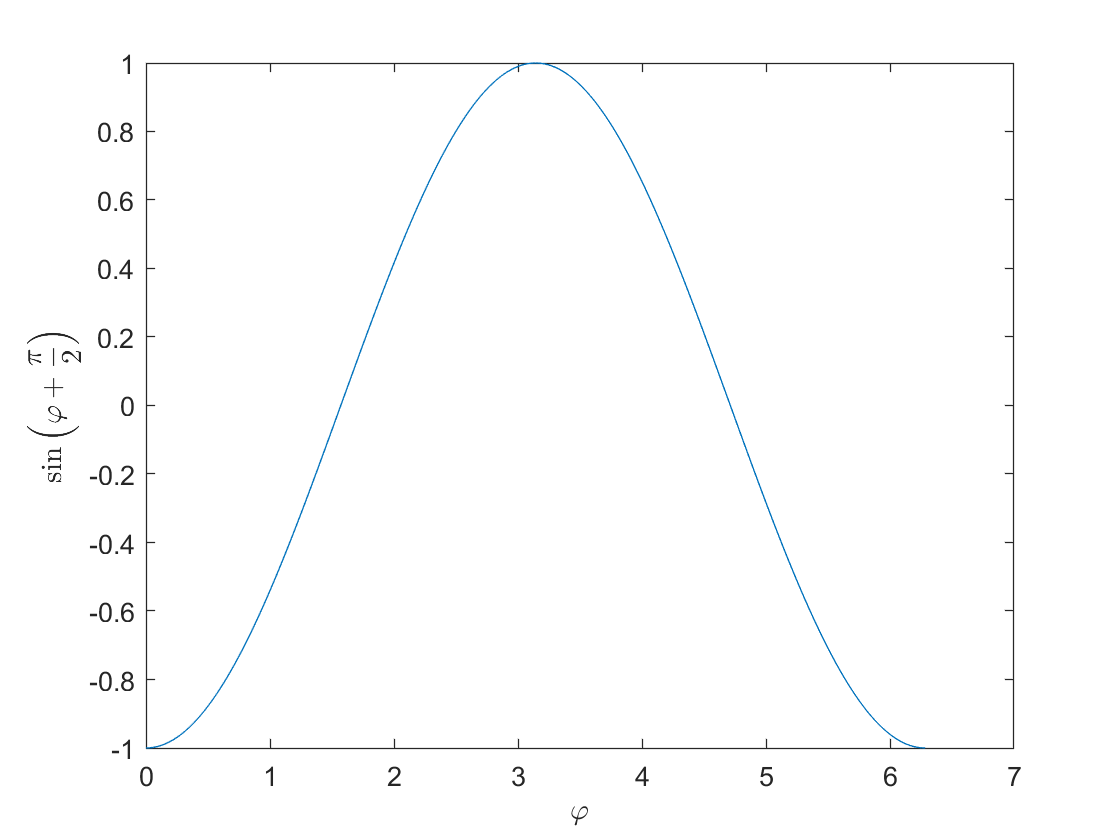

x = 0:0.01*pi:2*pi;
y = sin(x-pi/2);
plot(x,y);
xlabel('$$\varphi$$','Interpreter','latex');
ylabel('$$\sin\left(\varphi+\frac{\pi}{2}\right)$$','Interpreter','latex');

PD modulation of that sine wave can be written as

    $x_{\text{PD}}(\varphi) 
= x\big(\varphi_{\text{PD}}(\varphi)\big) 
= \sin\left(\varphi_{\text{PD}}(\varphi)-\frac{\pi}{2}\right)$.

Example for $a=2$:

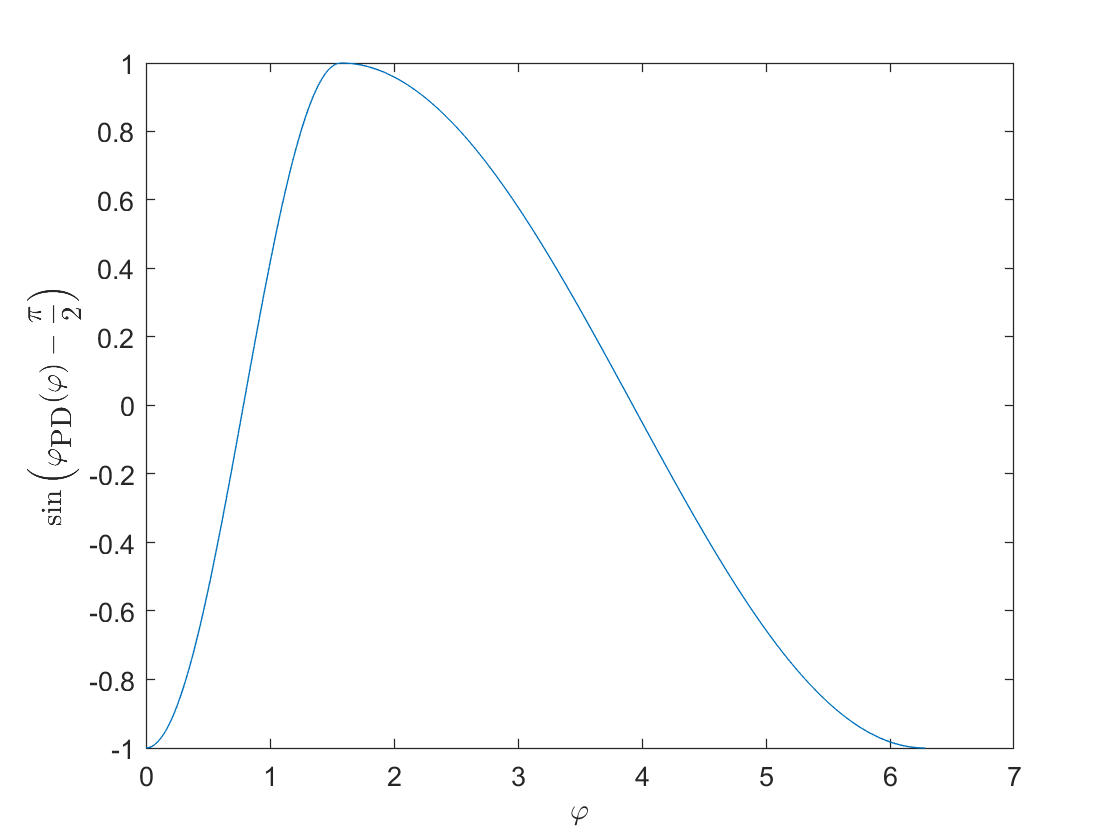

x = 0:0.01*pi:2*pi;
y = sin(PDMcc(x,2)-pi/2);
plot(x,y);
xlabel('$$\varphi$$','Interpreter','latex');
ylabel('$$\sin\left(\varphi_{\mbox{PD}}(\varphi)-\frac{\pi}{2}\right)$$','Interpreter','latex');

### 2.2   Cutting Recorded Wavetable Samples

fprintf('2.2 Cutting Recorded Wavetable Samples');

2.2 Cutting Recorded Wavetable Samples

Wavetable samples recorded from VZ-1 were taken from the YouTube video "[Casio VZ-10M - Exploring the Synth and Sounds](https://www.youtube.com/watch?v=YF16PshtaMs)" by ProckGnosis, time index 13:20.8 through 13:51.3. The audio extract is in `<project>/waves/recordings/all.wav`. I manually cutted out the wavetable samples `SINE.wav`, `SAW1.wav`, ..., `SAW5.wav`, `NOISE1.wav`, and `NOISE2.wav` which also stored in `<project>/waves/recordings`. In the `SINE.wav` and `SAW<n>.wav` files I manually labelled one cycle: $k_S$ - start sample, $k_{\text{max}}$ - sample of phase distortion bend (corresponding to $\varphi_B$ and characteristic curve), and $k_E$ - end sample. The sampling frequency is 48 kHz in all recordings.

f_S   = 48000;
name  = {'SINE';'SAW1';'SAW2';'SAW3';'SAW4';'SAW5'};
k_S   = [58398;55574;59082;56997;60414;61943];
k_max = [58470;55628;59109;57013;60424;61950];
k_E   = [58543;55719;59227;57142;60559;62088];
K     = k_E-k_S;
k_1   = k_max-k_S;
f_0   = f_S./K;
a     = K./(2.*k_1);
theta = a2theta(a);
T = table(name,k_S,k_max,k_E,K,k_1,f_0,a,theta);
fprintf('Cutting and PDM parameters of recorded wavetable samples:');

Cutting and PDM parameters of recorded wavetable samples:

T

T = 6×9 table
     name      k_S     k_max     k_E      K     k_1     f_0        a       theta 
    ______    _____    _____    _____    ___    ___    ______    ______    ______

    'SINE'    58398    58470    58543    145    72     331.03    1.0069     179.6
    'SAW1'    55574    55628    55719    145    54     331.03    1.3426    165.22
    'SAW2'    59082    59109    59227    145    27     331.03    2.6852    141.99
    'SAW3'    56997    57013    57142    145    16     331.03    4.5313    131.78
    'SAW4'    60414    60424    60559    145    10     331.03      7.25    126.09
    'SAW5'    61943    61950    62088    145     7     331.03    10.357    123.23


Reading ../waves/recordings/SINE.wav ...


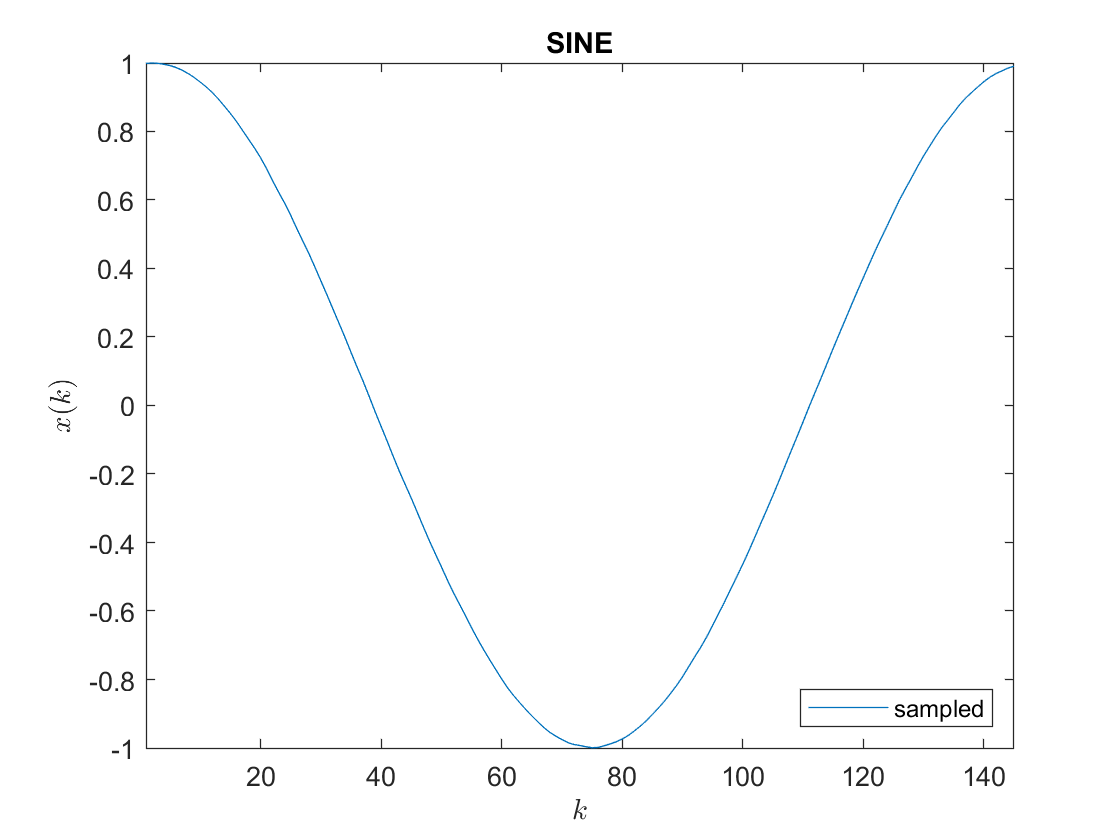

Writing ../waves/wavetable/sampled/SINE.wav ...


Reading ../waves/recordings/SAW1.wav ...


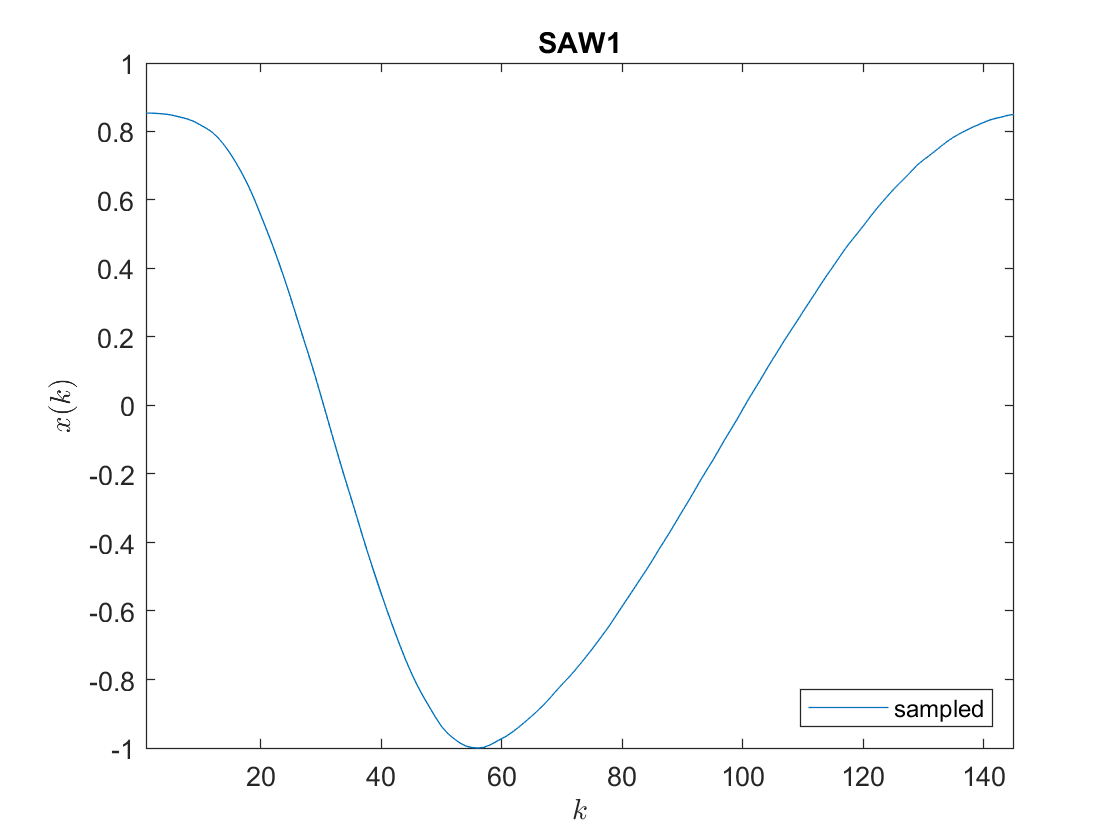

Writing ../waves/wavetable/sampled/SAW1.wav ...


Reading ../waves/recordings/SAW2.wav ...


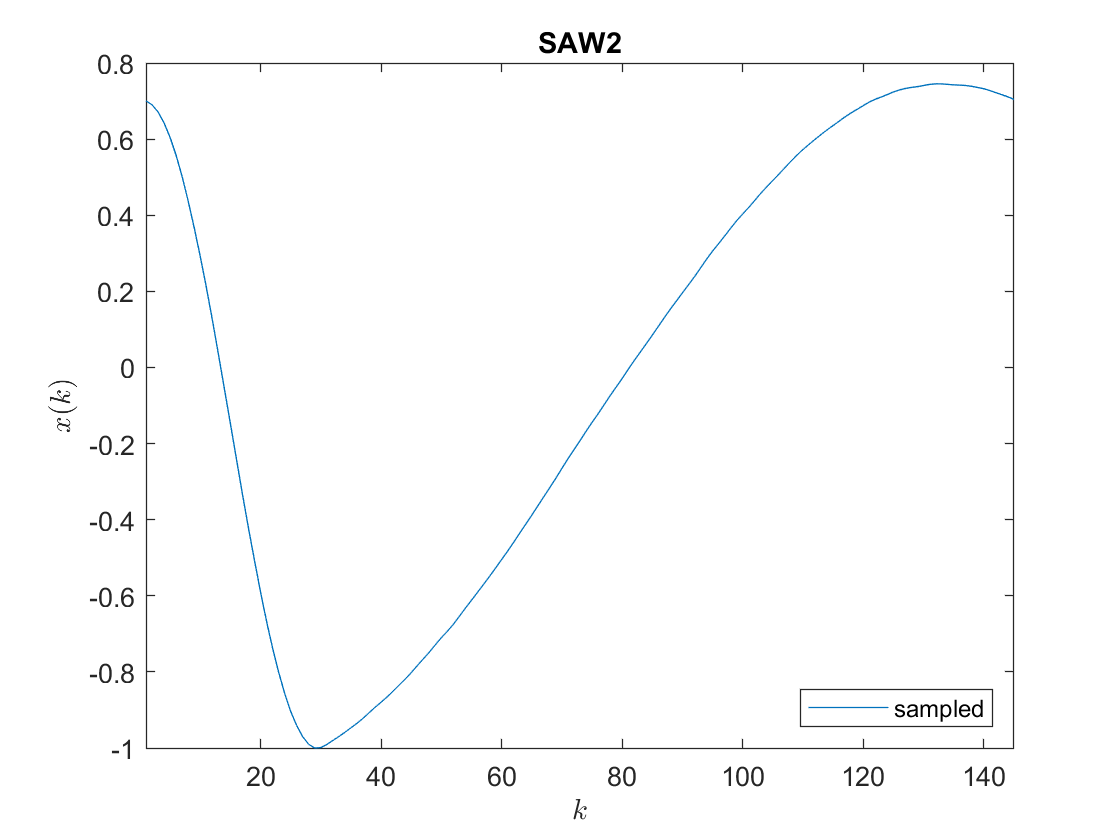

Writing ../waves/wavetable/sampled/SAW2.wav ...


Reading ../waves/recordings/SAW3.wav ...


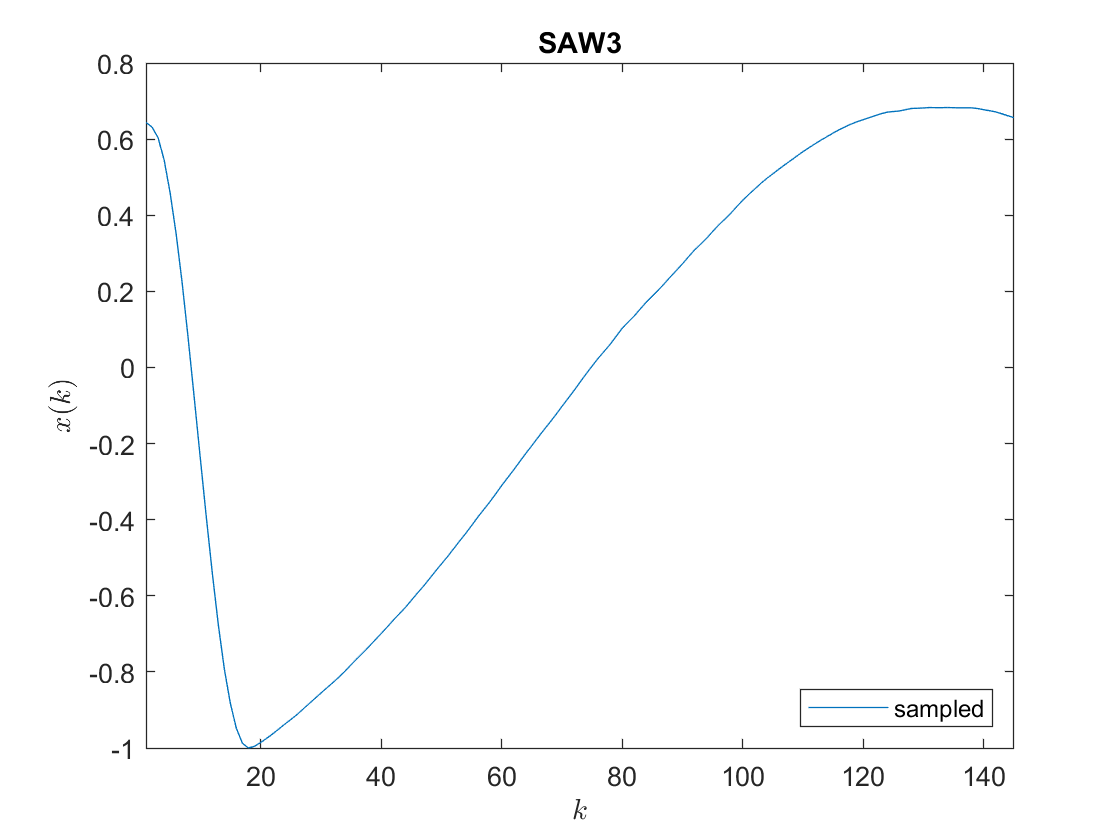

Writing ../waves/wavetable/sampled/SAW3.wav ...


Reading ../waves/recordings/SAW4.wav ...


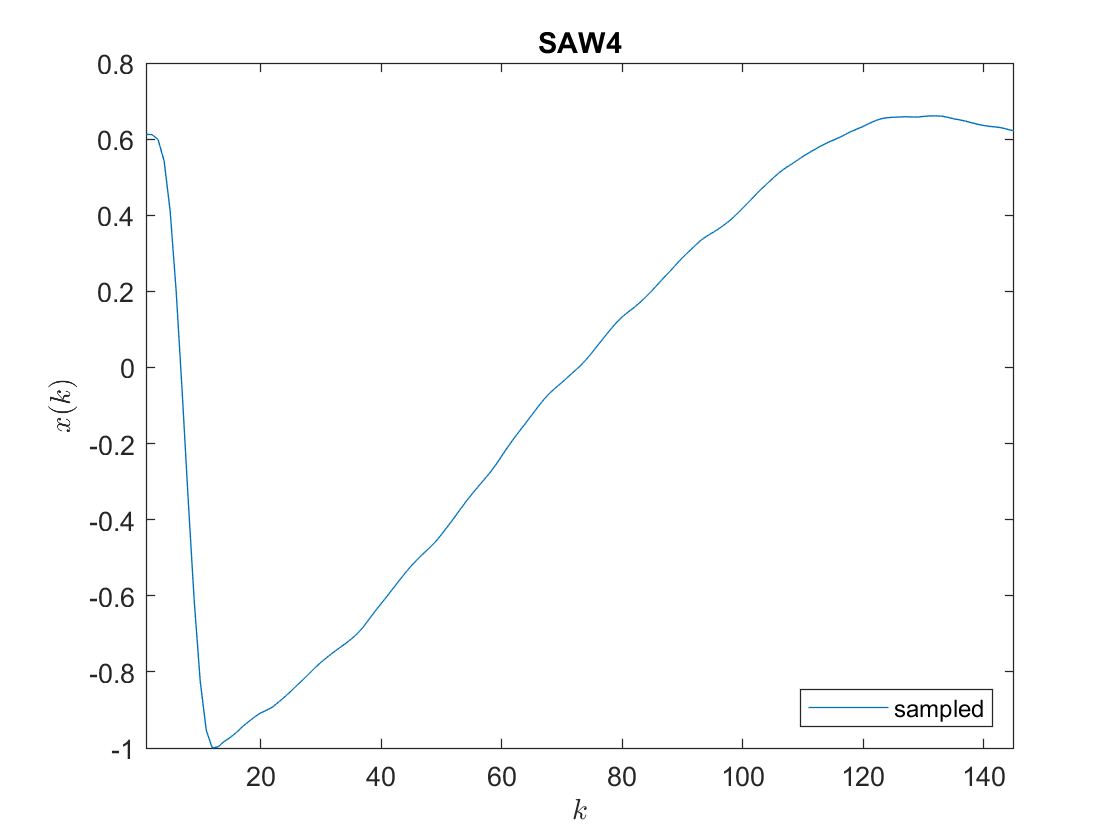

Writing ../waves/wavetable/sampled/SAW4.wav ...


Reading ../waves/recordings/SAW5.wav ...


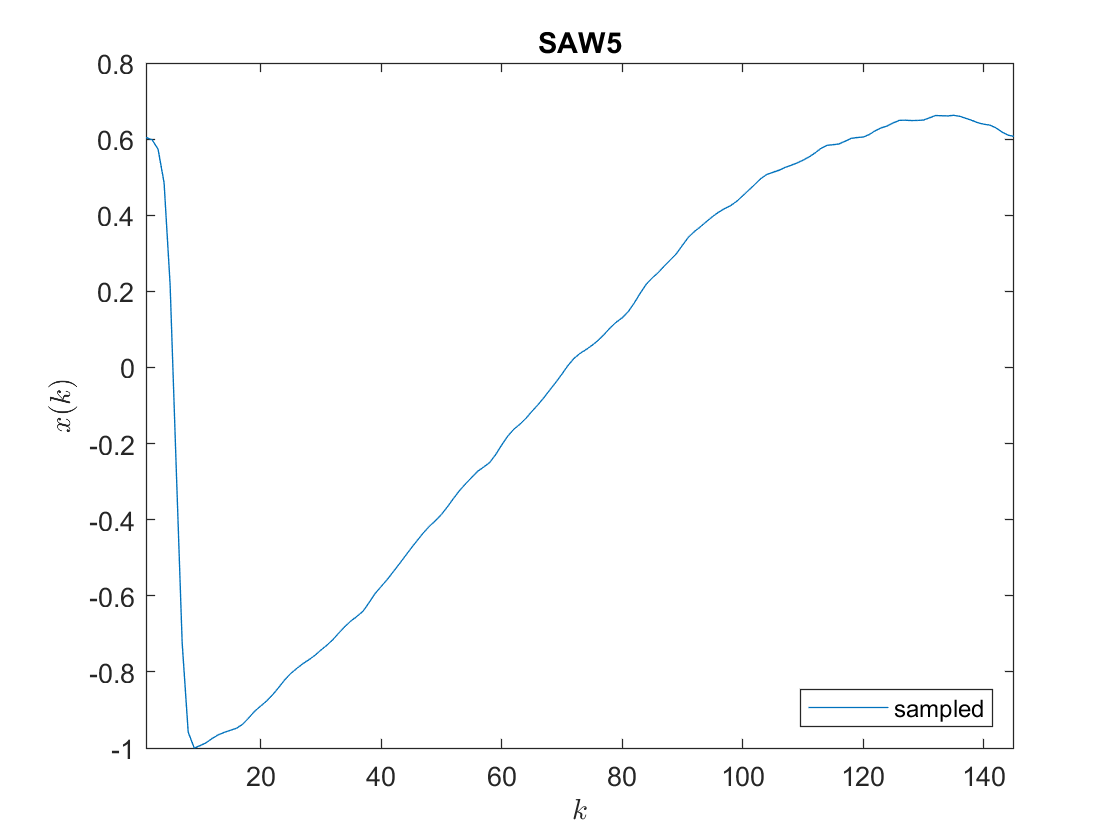

Writing ../waves/wavetable/sampled/SAW5.wav ...



N     = length(k_S);
waveR = cell(N);
for i=1:N
  fnIn  = ['../waves/recordings/'        T.name{i} '.wav'];
  fnOut = ['../waves/wavetable/sampled/' T.name{i} '.wav'];
  fprintf('Reading %s ...\n',fnIn);
  waveR{i} = audioread(fnIn,[T.k_S(i), T.k_E(i)-1]);
  waveR{i} = waveR{i}-mean(waveR{i});      % Remove DC
  waveR{i} = waveR{i}./max(abs(waveR{i})); % Normalize
  figure; plot(waveR{i});
  title(T.name{i});
  legend({'sampled'},'Location','southeast');
  xlabel('$$k$$'   ,'Interpreter','latex'); xlim([1 T.K(i)]);
  ylabel('$$x(k)$$','Interpreter','latex');
  fprintf('Writing %s ...\n',fnOut);
  audiowrite(fnOut,waveR{i},f_S);
end

### 2.3   Modeling the Wavetable Samples

fprintf('2.3 Modeling the Wavetable Samples');

2.3 Modeling the Wavetable Samples

For generating the waves, I use a sampling frequency $f_S=48\,\text{kHz}$ and a cycle length of $K=1024$ samples. Thus, the samples have a "natural" frequency of

    
$$f_0 = \frac{f_A}{K} = \frac{48000\,\text{Hz}}{1024} = 46.875\,\text{Hz}$$


which corresponds to the musical note F#1 plus 23 cents.

#### 2.3.1   Pure Phase Distortion of a Sine Wave

fprintf('2.3.1 Pure Phase Distortion of a Sine Wave');

2.3.1 Pure Phase Distortion of a Sine Wave

Removing unnecessary variables from the parameter table and correcting the settings for the SINE wave to $a_{\text{SINE}}=1$ and $\vartheta_{\text{SINE}}=180°$ yields:

T = removevars(T,{'k_S','k_max','k_E','k_1','f_0'}); % Remove cutting parameters  
T.a(1:1) = 1; T.theta(1:1) = 180;                    % Correct SINE parameters
fprintf('PDM wave generation parameters:');

PDM wave generation parameters:

T

T = 6×4 table
     name      K       a       theta 
    ______    ___    ______    ______

    'SINE'    145         1       180
    'SAW1'    145    1.3426    165.22
    'SAW2'    145    2.6852    141.99
    'SAW3'    145    4.5313    131.78
    'SAW4'    145      7.25    126.09
    'SAW5'    145    10.357    123.23


The first model produces the following PD-modulated waveforms:

Generating ../waves/wavetable/generated-purePDM/SINE.wav ...


Writing ../waves/wavetable/sampled/SAW5.wav ...


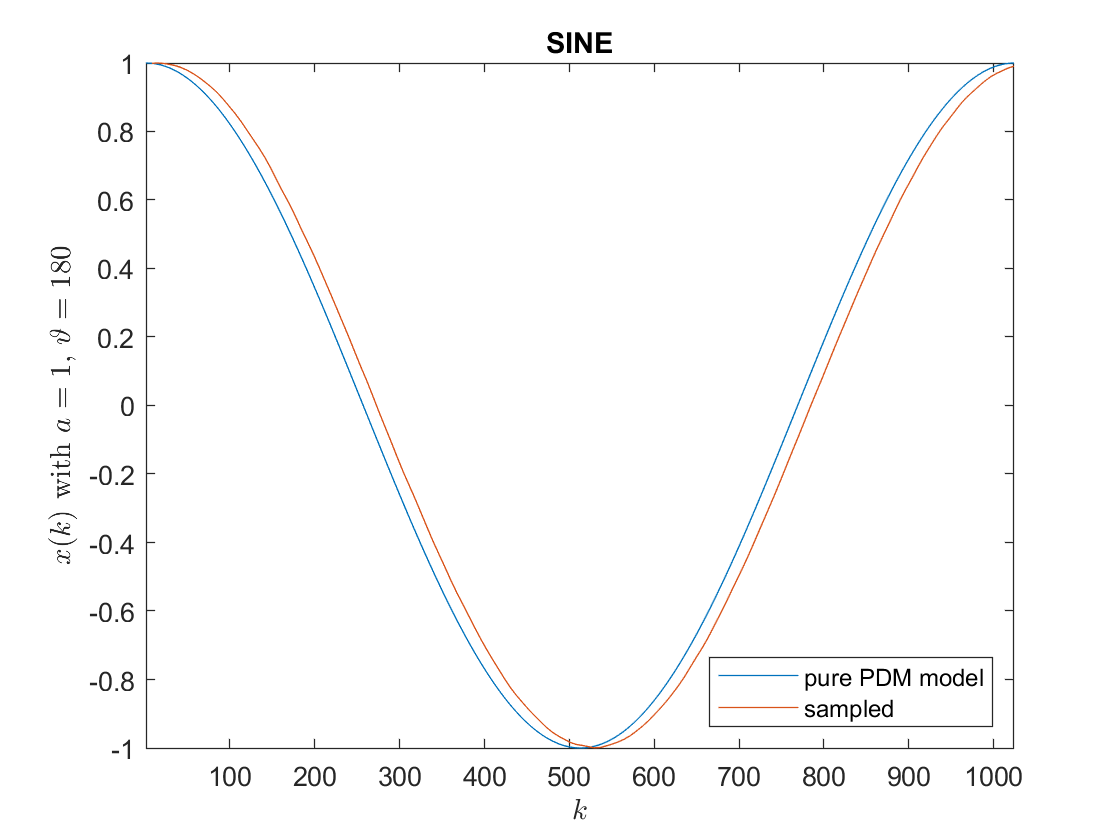

Generating ../waves/wavetable/generated-purePDM/SAW1.wav ...


Writing ../waves/wavetable/sampled/SAW5.wav ...


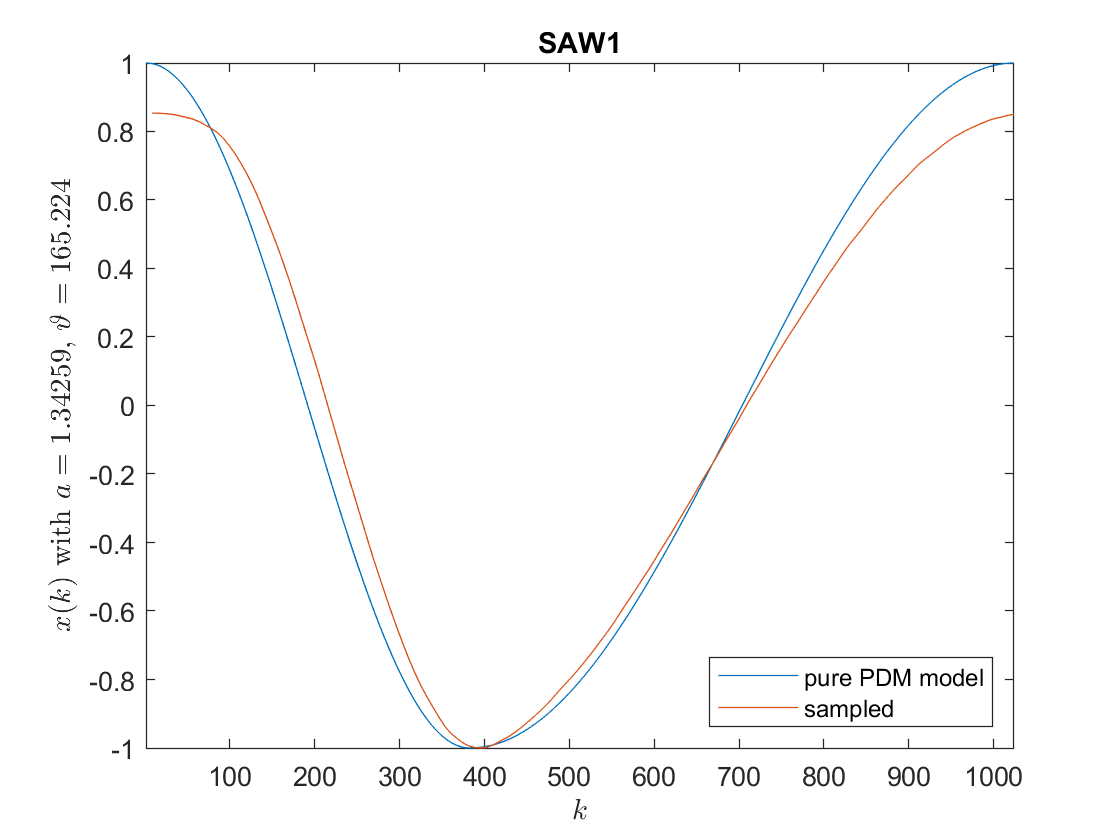

Generating ../waves/wavetable/generated-purePDM/SAW2.wav ...


Writing ../waves/wavetable/sampled/SAW5.wav ...


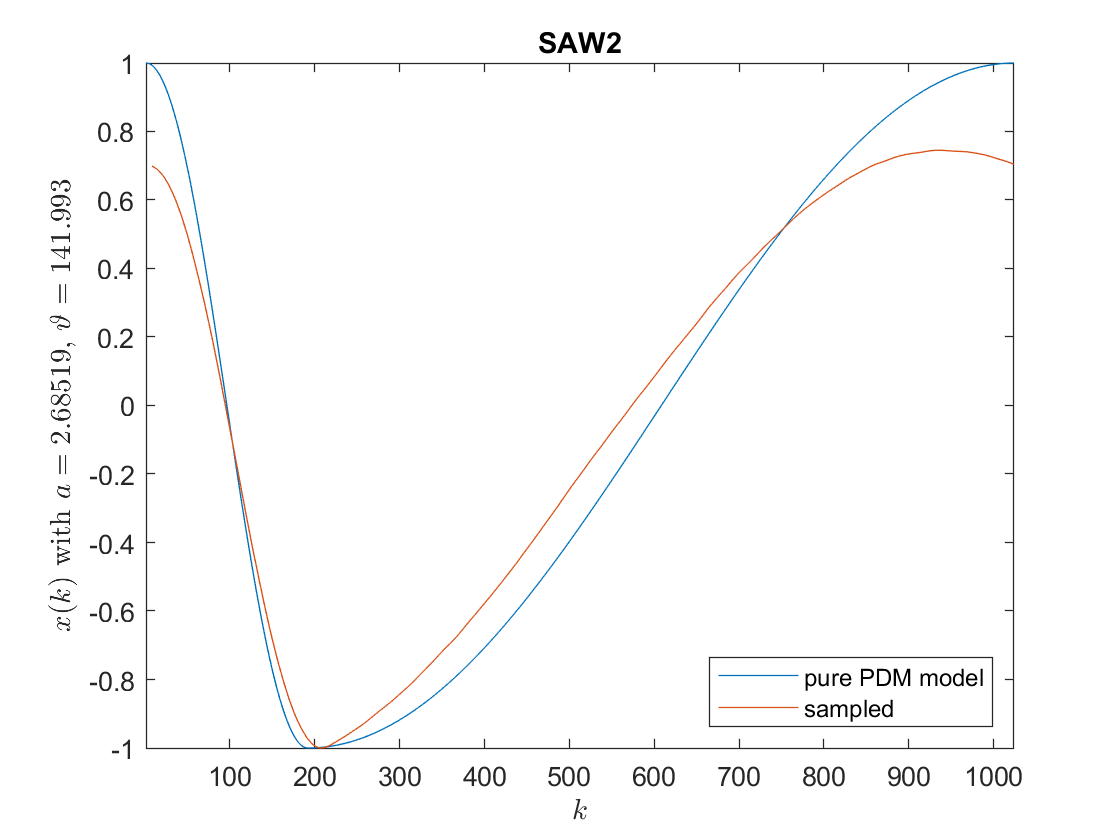

Generating ../waves/wavetable/generated-purePDM/SAW3.wav ...


Writing ../waves/wavetable/sampled/SAW5.wav ...


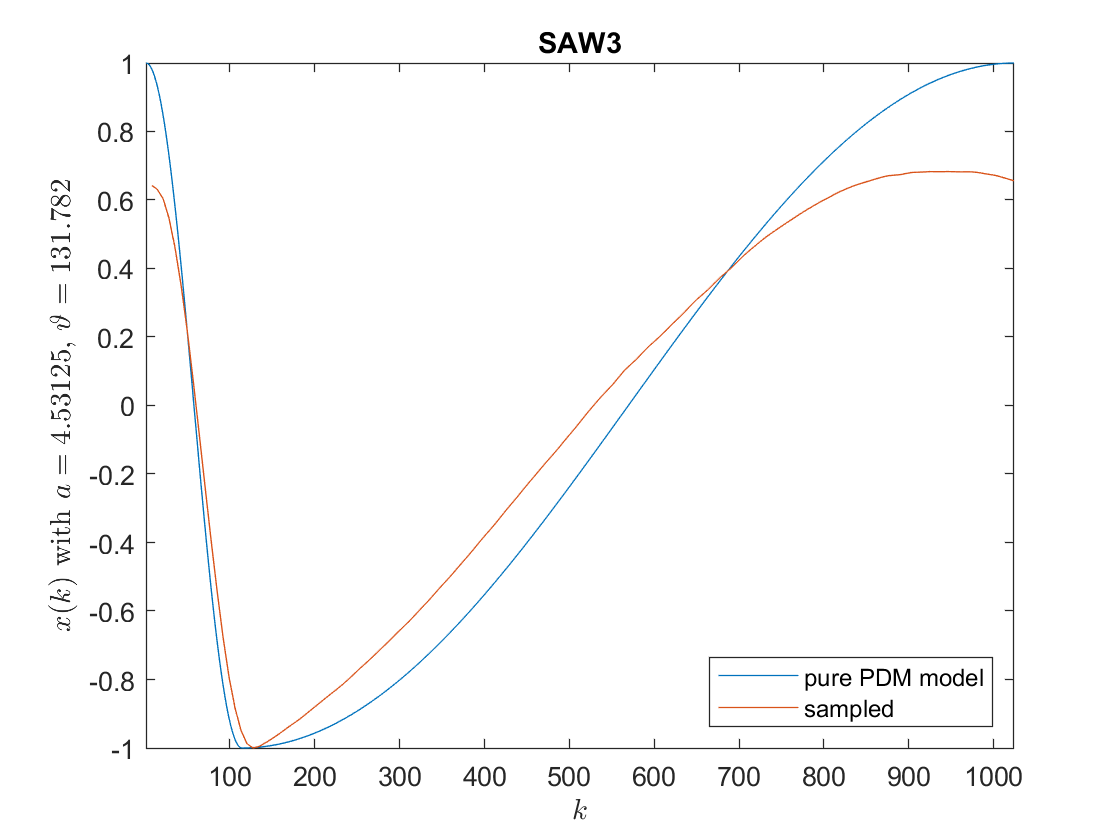

Generating ../waves/wavetable/generated-purePDM/SAW4.wav ...


Writing ../waves/wavetable/sampled/SAW5.wav ...


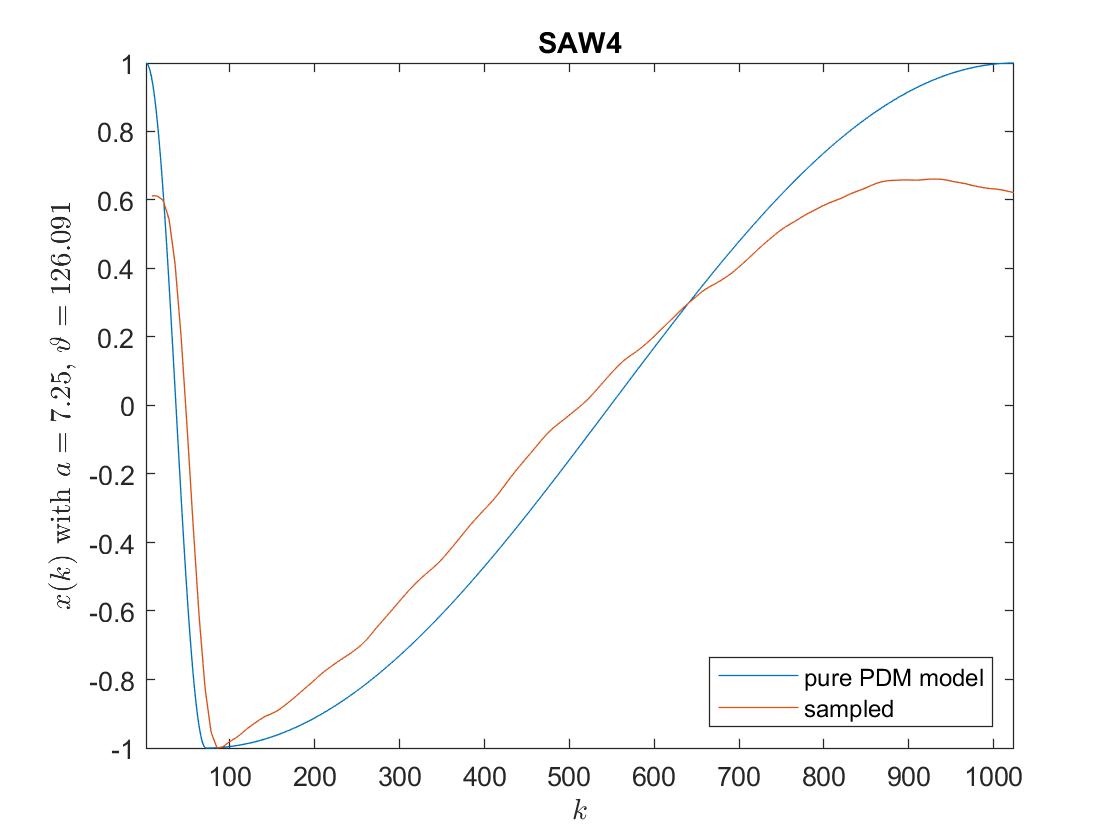

Generating ../waves/wavetable/generated-purePDM/SAW5.wav ...


Writing ../waves/wavetable/sampled/SAW5.wav ...


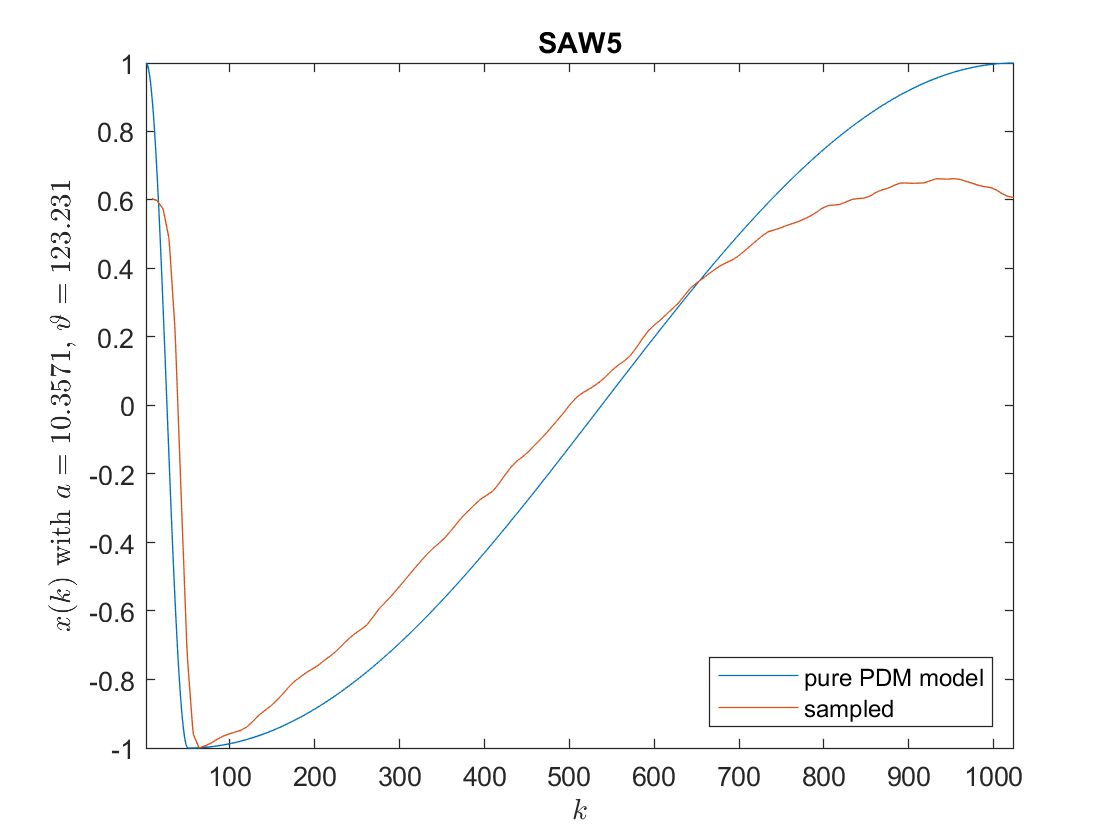

waveC{i} = cell(N);
K = 1024;
for i=1:N
  fn = ['../waves/wavetable/generated-purePDM/' T.name{i} '.wav'];
  fprintf('Generating %s ...\n',fn);
  k  = 0:K-1;
  waveC{i} = -sin(PDMcc(k/K*2*pi,T.a(i))-pi/2);         % 1)
  waveC{i} = waveC{i}-mean(waveC{i});                   % Remove DC
  waveC{i} = waveC{i}./max(abs(waveC{i}));              % Normalize
  waveRr   = interp1(1:T.K(i),waveR{i},(1:K)/K*T.K(i)); % Resample recorded wave
  fprintf('Writing %s ...\n',fnOut);
  audiowrite(fn,waveC{i},f_S);
  figure;
  plot(waveC{i}); hold on;
  plot(waveRr  ); hold off;
  legend({'pure PDM model','sampled'},'Location','southeast');
  title(T.name{i});
  xlim([1 K]);
  ylab = sprintf('$$x(k)$$ with $$a=%g$$, $$\\vartheta=%g$$',T.a(i),T.theta(i));
  xlabel('$$k$$','Interpreter','latex');
  ylabel(ylab   ,'Interpreter','latex');
end

1) VZ-1 seems to produce the inverted waveforms, hence the minus. **[TODO: **To be checked again!**]**

#### 2.3.2   Model Refinement

fprintf('2.3.2 Model Refinement');

2.3.2 Model Refinement

Comparing the sampled and generated waveforms in the plots above reveals an phase shift of the sampled version (see beginnings and endings of samples waveforms). I try to capture this by introduce a phase shift parameter $\varphi_0$ into the characteristic curve. As the transition from speed-up to slow-down---i.e., the "bend" of the chcracteristic---must still occur at the minimum of the input inverted cosine, I modify the bend point of the characteristic as follows:

    $f_1(\varphi)=a\varphi$,        $0\leq\varphi\leq\varphi_B$,    running through the points $(0,0)$ and $(\varphi_B,\pi-\varphi_0)$ and

    $f_2(\varphi) = b\varphi+c$,  $\varphi_B\leq \varphi< 2\pi$,  running through the points $(\varphi_B,\pi-\varphi_0)$ and $(2\pi,2\pi)$.

Taking $a$ and $\varphi_0$ as the free parameters, we obtain a new characteristic curve optimized for the VZ wavetable samples:

syms a b c phi phiB phi0 real;
assume(a>=0 & -pi<phi0 & phi0<pi);
eqns = [               ...
  a*phiB   == pi-phi0, ...
  b*phiB+c == pi-phi0, ...
  b*2*pi+c == 2*pi     ...
];
S = solve(eqns,[phiB,b,c]);
phiB  = simplify(S.phiB);  fprintf('  phiB ='                 ); disp(phiB);

  phiB =

$$-\frac{\varphi_{0}-\pi }{a}$$

b     = simplify(S.b);     fprintf('  b ='                    ); disp(b);

  b =

$$\frac{a\,\left(\varphi_{0}+\pi \right)}{\varphi_{0}-\pi +2\,\pi \,a}$$

c     = simplify(S.c);     fprintf('  c ='                    ); disp(c);

  c =

$$-\frac{2\,\pi \,\left(\varphi_{0}-\pi \right)\,\left(a-1\right)}{\varphi_{0}-\pi +2\,\pi \,a}$$

phiVZ = simplify(b*phi+c); fprintf('  phiVZ(phi) = b*phi+c = '); disp(phiVZ);

  phiVZ(phi) = b*phi+c = 

$$\frac{a\,\varphi \,\left(\varphi_{0}+\pi \right)}{\varphi_{0}-\pi +2\,\pi \,a}-\frac{2\,\pi \,\left(\varphi_{0}-\pi \right)\,\left(a-1\right)}{\varphi_{0}-\pi +2\,\pi \,a}$$

The formula of the characteristic is

    
$$\varphi_{\text{VZ}}(\varphi)
= \begin{cases}
    a\varphi 
    & \text{for } 0\leq\varphi<\frac{\pi-\phi_0}{a}
    \\
    \frac{a(\varphi_0+\pi)\,\varphi-2\pi(\varphi_0-\pi)(a-1)}{\varphi_0-\pi+2\pi a}
    & \text{for } \frac{\pi-\phi_0}{a}\leq\varphi<2\pi
   \end{cases}$$


and the phase-modulated waveforms can be expressed as

    
$$x_\text{VZ}(t) = \sin\left(\varphi_{\text{VZ}}(\varphi)+\frac{\pi}{2}+\varphi_0\right).$$


Using this improved model, I manually fittet the parameters $a$ and $\varphi_0$ for all waveforms. To compensate for little phase offsets from manual labelling of the recorded waveforms I introduce a circular shift of $c_s$ samples for plotting the waveforms generated by the improved model.

waveCR{i} = cell(N);
%         SINE  SAW1     SAW2     SAW3     SAW4     SAW5
a     = [ 1   ; 1.4    ; 2.3    ; 4      ; 7      ; 1000   ];
phi_0 = [ 0   ; 0.10*pi; 0.11*pi; 0.10*pi; 0.15*pi; 0.15*pi];
cs    = [20   ; 70     ; 10     ; 15     ; 20     ; 40     ]; % circular shift (for plot only)
theta = a2theta(a);
T = table(name,a,theta,phi_0,cs);
fprintf('PDM wave generation parameters (refined model):');

PDM wave generation parameters (refined model):

T

T = 6×5 table
     name      a      theta      phi_0     cs
    ______    ____    ______    _______    __

    'SINE'       1       180          0    20
    'SAW1'     1.4    163.41    0.31416    70
    'SAW2'     2.3    146.07    0.34558    10
    'SAW3'       4    133.78    0.31416    15
    'SAW4'       7    126.43    0.47124    20
    'SAW5'    1000    116.63    0.47124    40


Generating ../waves/wavetable/generated-optimized4VZ/SINE.wav ...


Writing ../waves/wavetable/sampled/SAW5.wav ...


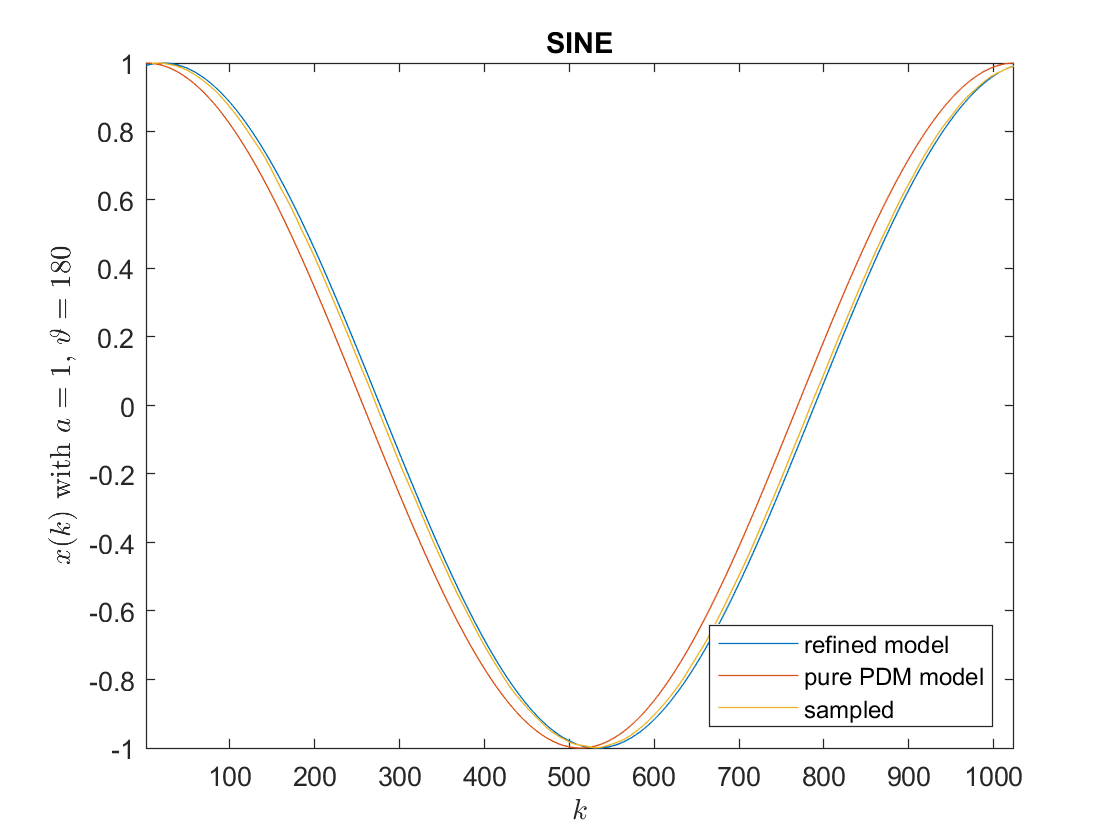

Generating ../waves/wavetable/generated-optimized4VZ/SAW1.wav ...


Writing ../waves/wavetable/sampled/SAW5.wav ...


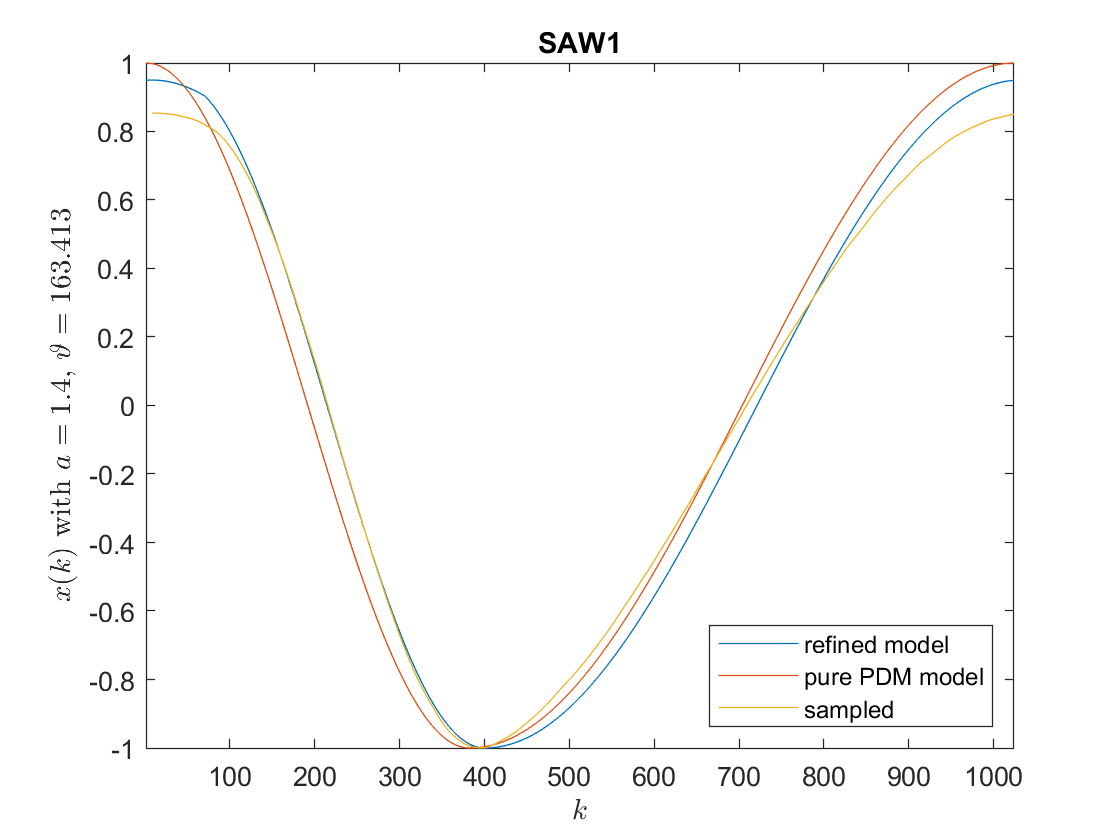

Generating ../waves/wavetable/generated-optimized4VZ/SAW2.wav ...


Writing ../waves/wavetable/sampled/SAW5.wav ...


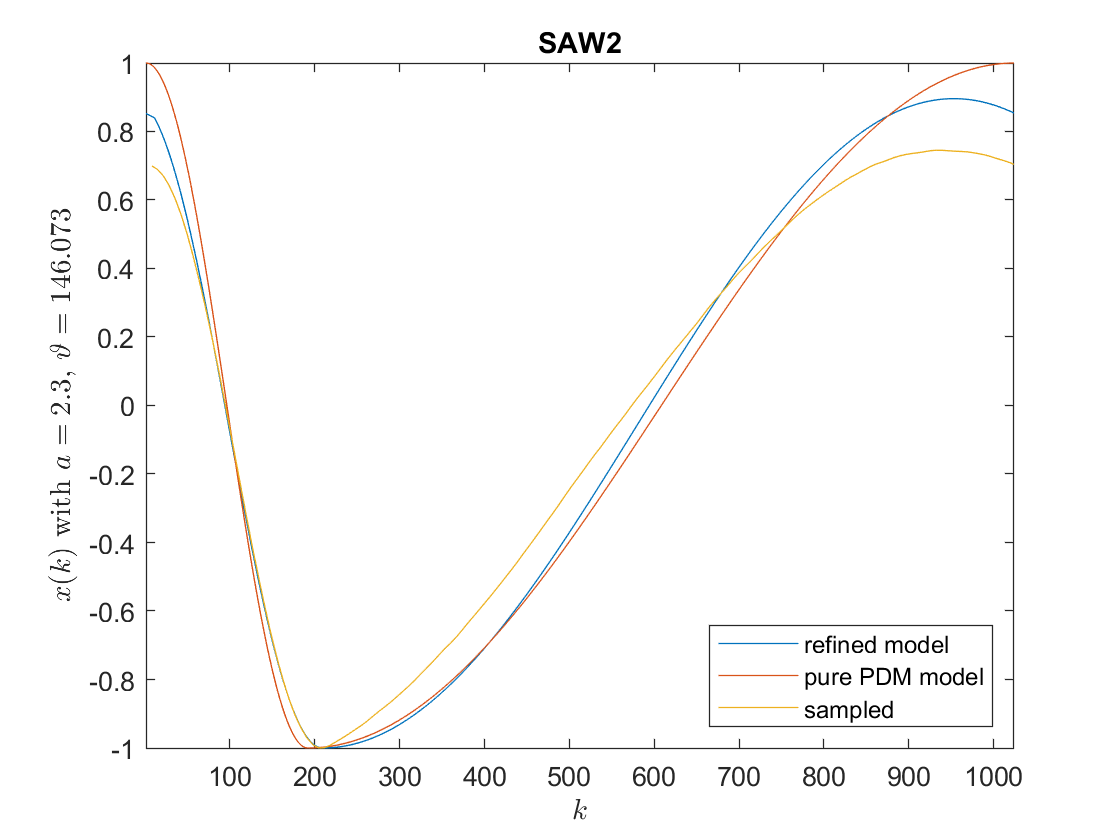

Generating ../waves/wavetable/generated-optimized4VZ/SAW3.wav ...


Writing ../waves/wavetable/sampled/SAW5.wav ...


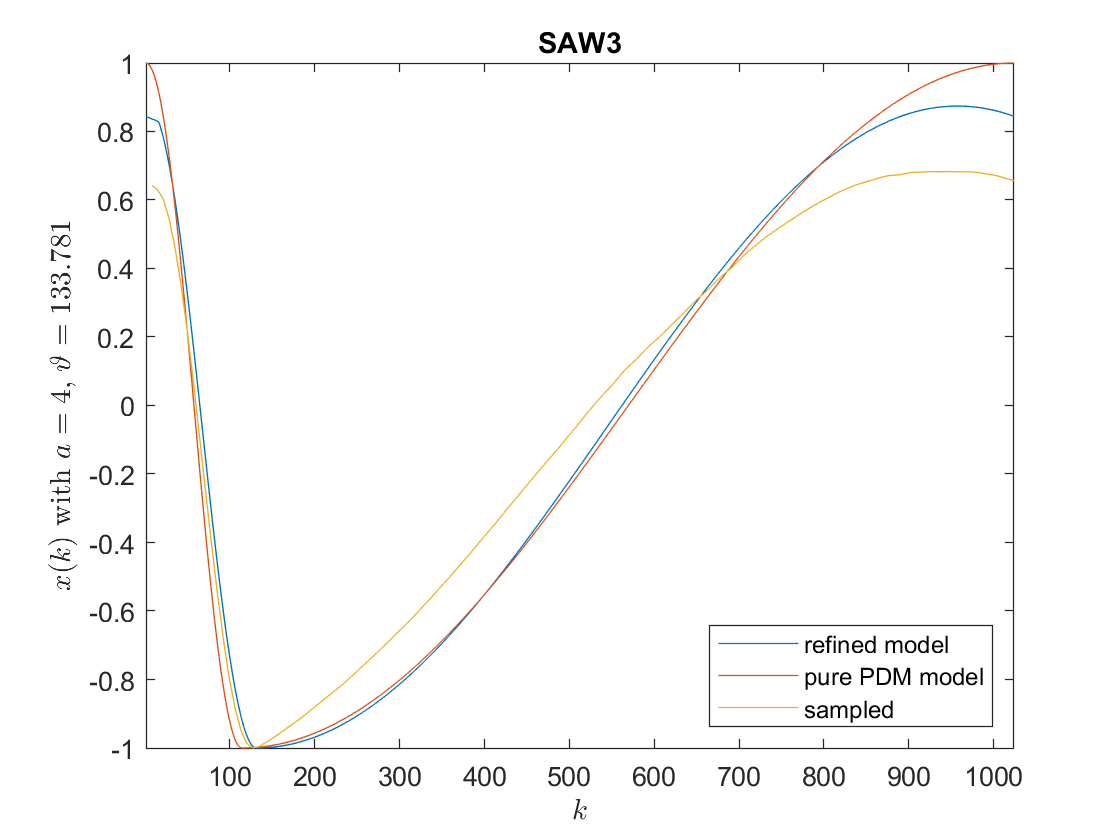

Generating ../waves/wavetable/generated-optimized4VZ/SAW4.wav ...


Writing ../waves/wavetable/sampled/SAW5.wav ...


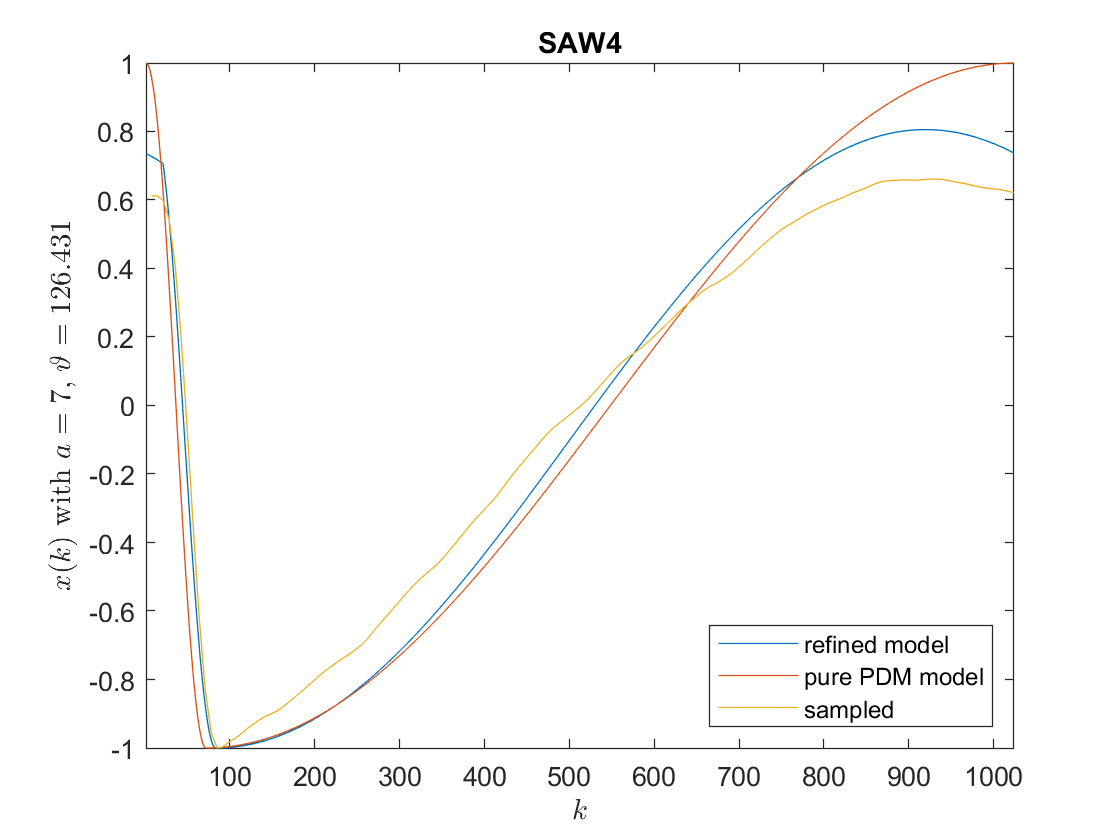

Generating ../waves/wavetable/generated-optimized4VZ/SAW5.wav ...


Writing ../waves/wavetable/sampled/SAW5.wav ...


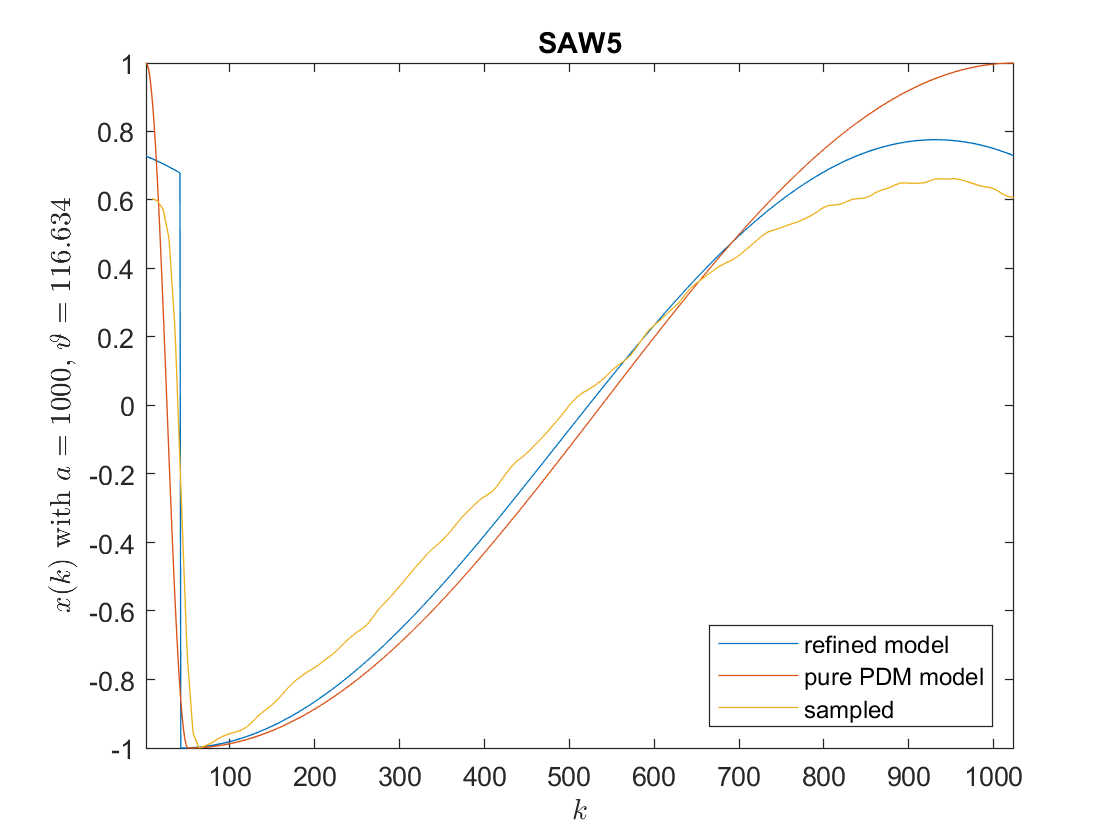


for i=1:N
  fn = ['../waves/wavetable/generated-optimized4VZ/' T.name{i} '.wav'];
  fprintf('Generating %s ...\n',fn);
  k  = 0:K-1;
  waveCR{i} = sin(PDMccVZ(k/K*2*pi,T.a(i),T.phi_0(i))+pi/2+T.phi_0(i));
  waveCR{i} = waveCR{i}-mean(waveCR{i});                                    % Remove DC
  waveCR{i} = waveCR{i}./max(abs(waveCR{i}));                               % Normalize
  waveRr   = interp1(1:length(waveR{i}),waveR{i},(1:K)/K*length(waveR{i})); % Resample recorded wave
  fprintf('Writing %s ...\n',fnOut);
  audiowrite(fn,waveCR{i},f_S);
  figure;
  plot(circshift(waveCR{i},T.cs(i))); hold on;
  plot(waveC{i}                    ); 
  plot(waveRr                      ); hold off;
  legend({'refined model','pure PDM model','sampled'},'Location','southeast');
  title(T.name{i});
  xlim([1 K]);
  ylab = sprintf('$$x(k)$$ with $$a=%g$$, $$\\vartheta=%g$$',T.a(i),T.theta(i));
  xlabel('$$k$$','Interpreter','latex');
  ylabel(ylab   ,'Interpreter','latex');
end

Even though the improved model produces slightly more accurate results than the pure PDM, there remain significant differences to the sampled waveforms. Particulary, the rising slope of the slowed-down second half-waves of `SAW3`...`SAW5` is almost linear in the sampled waveforms. This cannot be attained by a piecewise linear PDM characteristic at all. For fitting the original even better it seems most practicable to resort to spline interpolation and to renounce PDM altogether.

**[TODO:** Check whether $a$ and/or $\varphi_0$ depend on pitch or other parameters!**]**

## Appendix A    Local Functions

### A.1   Convert Slope Parameter to Modulation Angle Parameter

function theta = a2theta(a) 
  theta = (pi-atan(a)+atan(a./(2*a-1)))/pi*180;
end

### A.2   Modulation Angle Parameter to Slope Parameter

function aparam = theta2a(theta)
  aparam = theta;
  syms a real;
  assume(a>=1);
  for i=1:length(theta)
    t = theta(i)/180*pi;
    S = solve(t==pi-atan(a)+atan(a/(2*a-1)),a);
    aparam(i) = eval(S);
  end
end

### A.3   Phase Distortion Characteristic Curves

#### A.3.1   Original Phase Distortion Modulation

function phipd = PDMcc(phi,a)
  assert(all(phi>=0) && all(phi<=2*pi));
  phiB = pi./a;
  phipd = (phi<=phiB).*a.*phi + (phi>phiB).*(a.*phi+2*pi*(a-1))/(2*a-1);
end

#### A.3.2   Fitted for VZ Waveforms

function phipd = PDMccVZ(phi,a,phi0)
  assert(all(phi>=0) && all(phi<=2*pi));
  phiB = (pi-phi0)./a;
  phipd = (phi<=phiB).*a.*phi + (phi>phiB).*(a.*(phi0+pi).*phi-2*pi*(phi0-pi)*(a-1))/(phi0-pi+2*pi*a);
end